This script will examine some transport properites to compare core, peripheral, and interstitial transports.  You'll need [BetaEddyOne](https://zenodo.org/records/8200056), [jLab](https://github.com/jonathanlilly/jLab), and the [Crameri colormaps](https://www.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps).

%------------------------------------------------------------------------
%Load the data
%This is when your NetCDF file is kept
ncdir='/Users/lilly/Desktop/Dropbox/NetCDF/';
filename='BetaEddyOne.nc';

%loading in data
lato=ncread([ncdir filename],'latitude');
fo=abs(corfreq(lato))/3600; %rad/s

x=ncread([ncdir filename],'x')/1000;
y=ncread([ncdir filename],'y')/1000;
u=permute(squeeze(ncread([ncdir filename],'u')),[2 1 3]);
v=permute(squeeze(ncread([ncdir filename],'v')),[2 1 3]);
ssh=permute(squeeze(ncread([ncdir filename],'ssh')),[2 1 3]);
zeta=permute(squeeze(ncread([ncdir filename],'zeta')),[2 1 3])/fo;

drifter_x=ncread([ncdir filename],'drifter_x')'/1000;
drifter_y=ncread([ncdir filename],'drifter_y')'/1000;
drifter_u=ncread([ncdir filename],'drifter_u')';
drifter_v=ncread([ncdir filename],'drifter_v')';
drifter_t=vrep([1:size(drifter_x,1)]',size(drifter_x,2),2);%time for drifters
%------------------------------------------------------------------------
%Compute eddy center location and largest instanteous closed streamline
[xo,yo]=eddyCenter(x,y,ssh,0.9,method="timesMax");
[xp,yp,sshEddy]=createEddyFrame(x,y,xo,yo,300,ssh);

uo=vdiff(xo,1,'endpoint')*1000*100/(24*3600);%km/day to cm/s
vo=vdiff(yo,1,'endpoint')*1000*100/(24*3600);%km/day to cm/s

[psip,psi,psif] = eddyFrameStreamFunction(xp,yp,sshEddy,uo/100,vo/100,fo);

tic;
[xpc,ypc,levels,index]=largestClosedStreamline(xp,yp,psip,0.25);
toc

Elapsed time is 13.787111 seconds.


xc=celladd(xpc,xo);%put these contours back in the Earth frame
yc=celladd(ypc,yo);

%finally, mark particles as inside or outside trapping region 
isTrapped=markEnclosedParticles(drifter_x,drifter_y,xc,yc);
%------------------------------------------------------------------------

%Let's look at a trapping histogram
sum(mean(isTrapped,1)==1)./size(isTrapped,2) %always trapped 

ans = 0.0088

sum(mean(isTrapped,1)==0)./size(isTrapped,2) %never trapped

ans = 0.9649

sum(mean(isTrapped,1)~=0&mean(isTrapped,1)~=1)./size(isTrapped,2) %sometimes trapped

ans = 0.0263

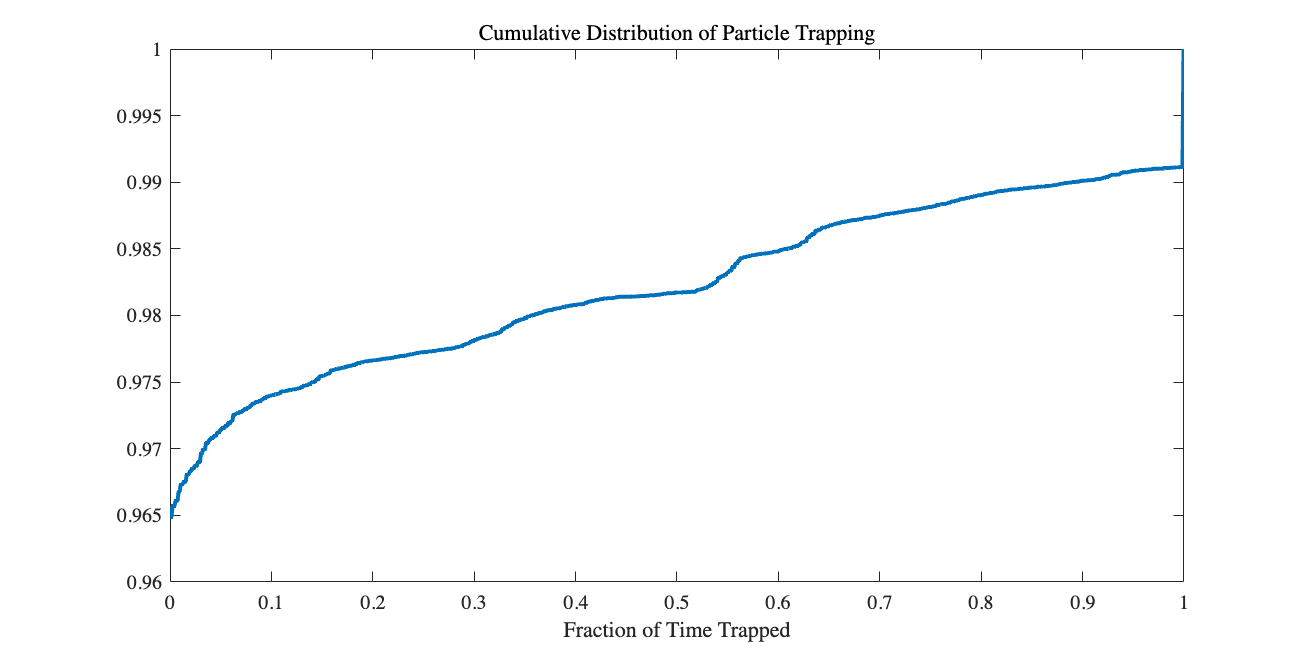


[n,xval]=hist(mean(isTrapped,1),1000);
hf = figure();
hf.Position(3:4) = [1200,600];
plot(xval,cumsum(n)./sum(n),linewidth=2)
title('Cumulative Distribution of Particle Trapping')
xlabel('Fraction of Time Trapped')

 Most particle (96.5%) are never trapped.  A little less than one percent (0.88%) are always trapped, and a bit more than two percent (2.6%) are sometimes trapped, according to this definition. 

Let's now compute the transport according to the particle identity using the Lagrangian fields.

dx = x(2)-x(1);%dx in km 
dA = dx.^2     %differential area in km^2, since dx=dy

dA = 15.2588

K = size(u,3); %number of time steps

%total area of fluid
max(x)*max(y)/1e6 %1.99 Mm^2

ans = 1.9883


%or if I attribute dA to each grid point
512*256*dA/1e6 %2 Mm^2

ans = 2

(max(x)+dx)*(max(y)+dx)/1e6 %2 Mm^2

ans = 2


%initial and final areas of the eddy
[~,~,~,R]=curvemoments(xc,yc);
Eo = pi*R(1)^2;   %44564 km^2
Ef = pi*R(end)^2; %32505 km^2

u_avg = reshape(mean(drifter_u,1),length(x),length(y))';
v_avg = reshape(mean(drifter_v,1),length(x),length(y))';

%------------------------------------------------------------------------------------
%east-west transport computations

%area of fluid particles with net east-west motion 
movesEast = (u_avg>0); 
Ae = sum(movesEast(:),1)*dA/1e6 % 1.23 Mm^2 moving east

Ae = 1.2305

Aw = sum(~movesEast(:),1)*dA/1e6 % 0.77 Mm^2 moving west

Aw = 0.7695


%what is the transport? 
sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/(2e6) %41 km/year

ans = 41.2614

sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/(2e6) %-41 km/year

ans = -41.3009

%a volume of fluid equal to the entire domain size moves 41 km east or west in a year 

%transport expressed in terms of intial eddy area 
sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/Eo %1852 km/year

ans = 1.8518e+03

sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/Eo %1852 km/year

ans = -1.8535e+03


%Let's compare this with distance the eddy moves
xo(end)-xo(1) %-1164 km/year

ans = -1.1642e+03


%So the total transport due to the eddy is about 1.5x what you would expect
%based only on the transport from what is inside the core 

sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/Eo/(xo(end)-xo(1)) %1.59

ans = -1.5906


%how far do the areas of eastward and westward moving fluid move?  
sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/(Ae*1e6)  %67 km/year

ans = 67.0670

sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/(Aw*1e6) %-107 km/year

ans = -107.3384


%the volume of westward-moving fluid is about 1/2 as large but moves 2x as far
%------------------------------------------------------------------------------------
%north-south transport computations

%area of fluid particles with net north-south motion 
movesNorth = (v_avg>0); 
An = sum(movesNorth(:),1)*dA/1e6 % 1.09 Mm^2 moving north

An = 1.0906

As = sum(~movesNorth(:),1)*dA/1e6 % 0.91 Mm^2 moving south

As = 0.9094


%what is the transport? 
sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/(2e6) %18 km/year

ans = 18.2292

sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/(2e6) %-18 km/year

ans = -18.2495

%a volume of fluid equal to the entire domain size moves 18 km east or west in a year 

%transport expressed in terms of intial eddy area 
sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/Eo %818 km/year

ans = 818.1028

sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/Eo %819 km/year

ans = -819.0157


%Let's compare this with distance the eddy moves
yo(end)-yo(1) %-210 km/year

ans = -210.0402


%So the total transport due to the eddy is about 4x what you would expect
%based only on the transport from what is inside the core 

sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/Eo/(yo(end)-yo(1)) %3.9

ans = -3.8950


%how far do the areas of eastward and westward moving fluid move?  
sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/(An*1e6)  %33 km/year

ans = 33.4289

sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/(As*1e6) %-40 km/year

ans = -40.1363


%the volume of northward moving fluid is only slightly larger than that of 
%southward moving fluid, hence the net transport are comparable
%------------------------------------------------------------------------------------

The takeaway: net north-south displacement is about 1/2 as large as net east-west dispacement, perhaps surprisingly.  

Let's visualize the dispacements according to the initial particle locations. 

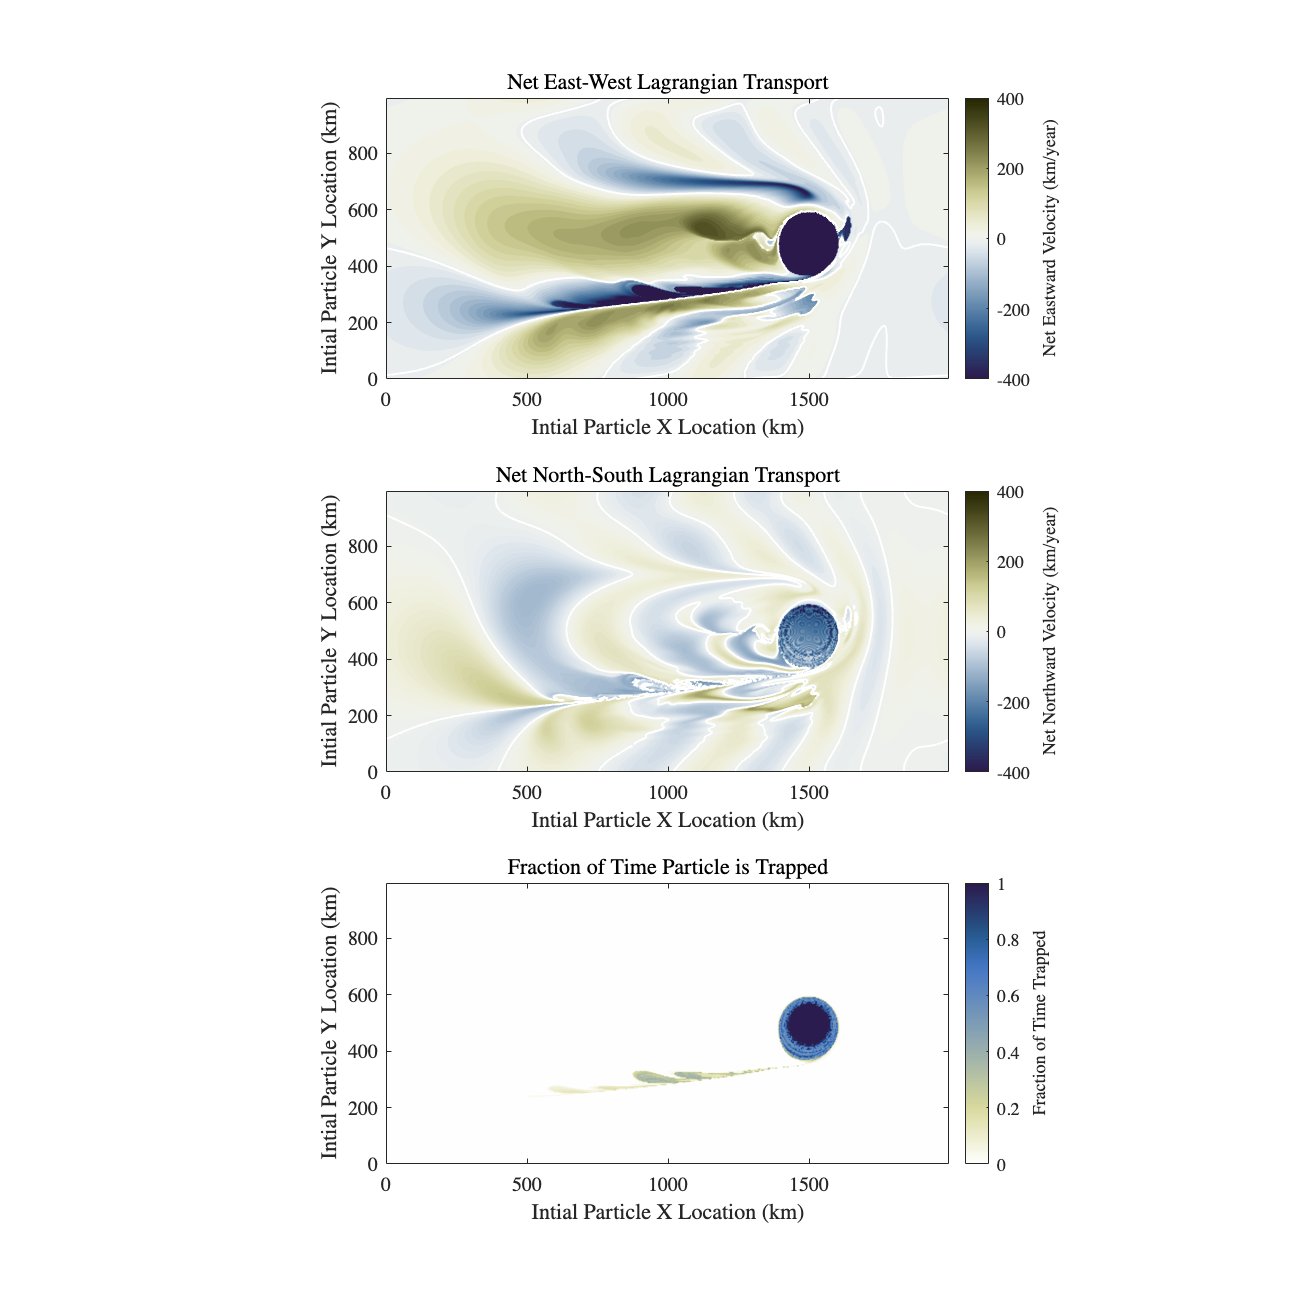

%the fraction of time a particle is within the largest closed streamline
trapFraction = reshape(mean(isTrapped,1),length(x),length(y))';

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(crameri('broc'))

tiledlayout(3,1);

nexttile;
contourf(x,y,u_avg*(24*3600*365)/1000,100),nocontours, hold on, axis equal 
contour(x,y,u_avg*(24*3600*365)/1000,[0 0],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Net Eastward Velocity (km/year)";
title("Net East-West Lagrangian Transport")
clim([-400 400])
xlabel('Intial Particle X Location (km)')
ylabel('Intial Particle Y Location (km)')

nexttile;
contourf(x,y,v_avg*(24*3600*365)/1000,100),nocontours, hold on, axis equal 
contour(x,y,v_avg*(24*3600*365)/1000,[0 0],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Net Northward Velocity (km/year)";
title("Net North-South Lagrangian Transport")
clim([-400 400])
xlabel('Intial Particle X Location (km)')
ylabel('Intial Particle Y Location (km)')

ax=nexttile;
contourf(x,y,trapFraction,100),nocontours, hold on, axis equal 
hc=colorbar('location','EastOutside');
hc.Label.String = "Fraction of Time Trapped";
title("Fraction of Time Particle is Trapped")
clim([0 1])
xlabel('Intial Particle X Location (km)')
ylabel('Intial Particle Y Location (km)')
colormap(ax,flipud(crameri('davos')))

Note the distinction between the amount of fluid that is trapped and the amount exhibiting systematic east-west or north-south motions. Natrually the eastward-moving fluid is not trapped, but much west-ward moving fluid is not trapped, either.  

Furthermore, whereas the north-south transport of the ambient fluid largely occurs along alternating stripes, the east-west transport regime really depends on the initial location relative to the eddy.  Roughly speaking, things at the same initial latitude as the eddy, which it must displace, will move eastward.  There are also prominent zonal bands of westward transport on the eddy flanks, and one band of prominent eastward transport on the south side of the eddy wake.  This complex behavior suggests several different modes of mediating east-west transport. 

Next we ask what fraction of the net transport is associated with trapping. 

%eastward motion associated with particles that are instantaneously trapped

uTrappedEastMoving = drifter_u;
uTrappedEastMoving(~isTrapped) = 0;
uTrappedEastMoving(drifter_u<0) = 0;
uTrappedEastMoving = reshape(mean(uTrappedEastMoving,1),length(x),length(y))';

uTrappedWestMoving = drifter_u;
uTrappedWestMoving(~isTrapped) = 0;
uTrappedWestMoving(drifter_u>0) = 0;
uTrappedWestMoving = reshape(mean(uTrappedWestMoving,1),length(x),length(y))';

%what is the transport? 
sum(uTrappedEastMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %21 km/year, about 1/2 (of 41)

ans = 21.5546

sum(uTrappedWestMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %-42 km/year, all      (of 41)

ans = -42.0378

%compare with -41.3.  Thus, 1/2 of the eastward transport is associated
%with fluid motions from particles that are instantaneously trapped, and all of
%the westward transport ... meaning, untrapped motions account for 1/2 of
%the eastward transport ... but, cancellations can be important here 

vTrappedNorthMoving = drifter_v;
vTrappedNorthMoving(~isTrapped) = 0;
vTrappedNorthMoving(drifter_v<0) = 0;
vTrappedNorthMoving = reshape(mean(vTrappedNorthMoving,1),length(x),length(y))';

vTrappedSouthMoving = drifter_v;
vTrappedSouthMoving(~isTrapped) = 0;
vTrappedSouthMoving(drifter_v>0) = 0;
vTrappedSouthMoving = reshape(mean(vTrappedSouthMoving,1),length(x),length(y))';

%what is the transport? 
sum(vTrappedNorthMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %28.5 km/year 

ans = 28.4837

sum(vTrappedSouthMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %-32 km/year

ans = -32.2879

%the north/south displacements due to trapping actually add up to more than
%the total north/south transport (18 km/year), suggesting temporal cancellation
%---------------------------------------------------------------------------------
%another version, find transport due to particles that are *ever* trapped

isEverTrapped=reshape(mean(isTrapped,1)~=0,length(x),length(y))';
sum(u_avg(movesEast&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.13 km/year (of 41)

ans = 0.1305

sum(u_avg(~movesEast&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-26 km/year (of 41)

ans = -26.0122

%this means that essentially all of the eastward transport, and about 1/2 of the
%westward transport, is associated with particles that are *never* trapped
sum(v_avg(movesNorth&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.37 km/year (of 18)

ans = 0.3704

sum(v_avg(~movesNorth&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-4.7 km/year (of 18)

ans = -4.7200

%again, essentially all of the northward transport, and about 3/4 of the
%southward transport, is associated with particles that are *never* trapped

isAlwaysTrapped=reshape(mean(isTrapped,1)==1,length(x),length(y))';
sum(u_avg(movesEast&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.0 km/year (of 41)

ans = 0

sum(u_avg(~movesEast&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-10 km/year (of 41)

ans = -10.3238

sum(v_avg(movesNorth&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0 km/year (of 18)

ans = 0

sum(v_avg(~movesNorth&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-1.8 km/year (of 18)

ans = -1.8470


isNeverTrapped=reshape(mean(isTrapped,1)==0,length(x),length(y))';
sum(u_avg(movesEast&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %41 km/year (of 41)

ans = 41.1309

sum(u_avg(~movesEast&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-15 km/year (of 41)

ans = -15.2888

sum(v_avg(movesNorth&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %17 km/year (of 18)

ans = 17.8587

sum(v_avg(~movesNorth&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-13 km/year (of 18)

ans = -13.5295


isSometimesTrapped=reshape(mean(isTrapped,1)~=0 & mean(isTrapped,1)~=1,length(x),length(y))';
sum(u_avg(movesEast&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.12 km/year (of 41)

ans = 0.1305

sum(u_avg(~movesEast&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-15 km/year (of 41)

ans = -15.6884

sum(v_avg(movesNorth&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.37 km/year (of 18)

ans = 0.3704

sum(v_avg(~movesNorth&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-2.8 km/year (of 18)

ans = -2.8730

This analysis shows that motions outside of the trapping region, on the eddy periphery, play a major role in transport.  We can clarify this in the following way. 

%compute some statistics centered on the eddy
bins=-250:2.5:250;
[mu,xmid,ymid,numz,stdu]=twodstats(drifter_x-xo,drifter_y-yo,drifter_u,bins,bins);
[mv,xmid,ymid,numz,stdv]=twodstats(drifter_x-xo,drifter_y-yo,drifter_v,bins,bins);
[mt,xmid,ymid,numz,stdt]=twodstats(drifter_x-xo,drifter_y-yo,isTrapped,bins,bins);

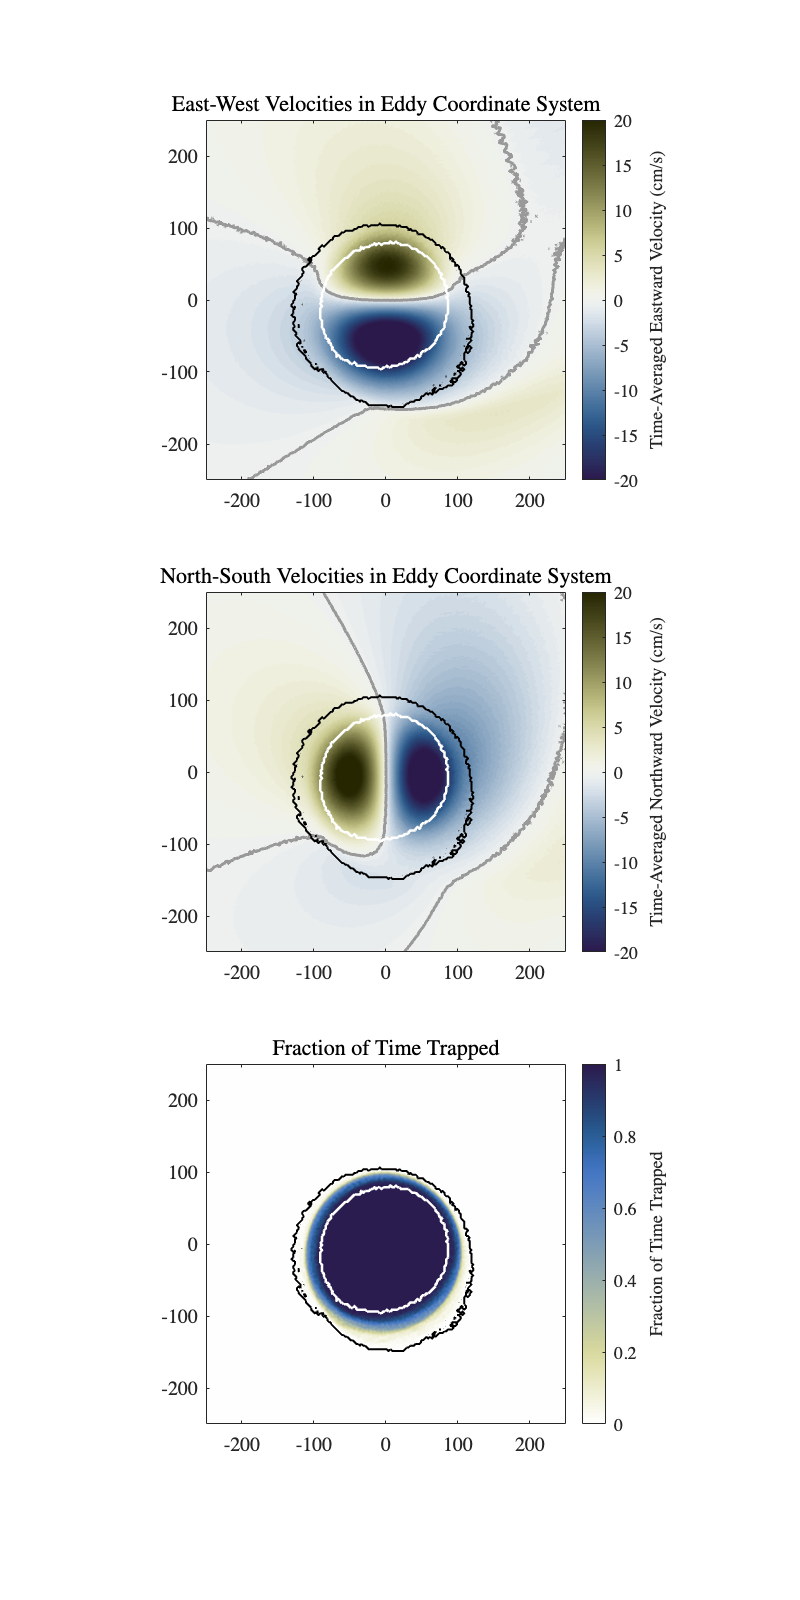

hf = figure();
hf.Position(3:4) = [1200,2400];
colormap(crameri('broc'))

tiledlayout(3,1);

nexttile;
contourf(xmid,ymid,100*mu,100),nocontours, hold on,axis equal
contour(xmid,ymid,100*mu,[0 0],linewidth=1.5,color=[1 1 1]*0.6)
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([-.2 .2]*100),axis([-1 1 -1 1]*250)
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25C')
title('East-West Velocities in Eddy Coordinate System')
hc=colorbar('location','EastOutside');
hc.Label.String = "Time-Averaged Eastward Velocity (cm/s)";

nexttile;
contourf(xmid,ymid,100*mv,100),nocontours, hold on,axis equal
contour(xmid,ymid,100*mv,[0 0],linewidth=1.5,color=[1 1 1]*0.6)
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([-.2 .2]*100),axis([-1 1 -1 1]*250)
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25C')
title('North-South Velocities in Eddy Coordinate System')
hc=colorbar('location','EastOutside');
hc.Label.String = "Time-Averaged Northward Velocity (cm/s)";

ax=nexttile;
contourf(xmid,ymid,mt,100),nocontours, hold on,axis equal
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([0 1]),axis([-1 1 -1 1]*250)
colormap(ax,flipud(crameri('davos')))
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25D')
title('Fraction of Time Trapped')
hc=colorbar('location','EastOutside');
hc.Label.String = "Fraction of Time Trapped";

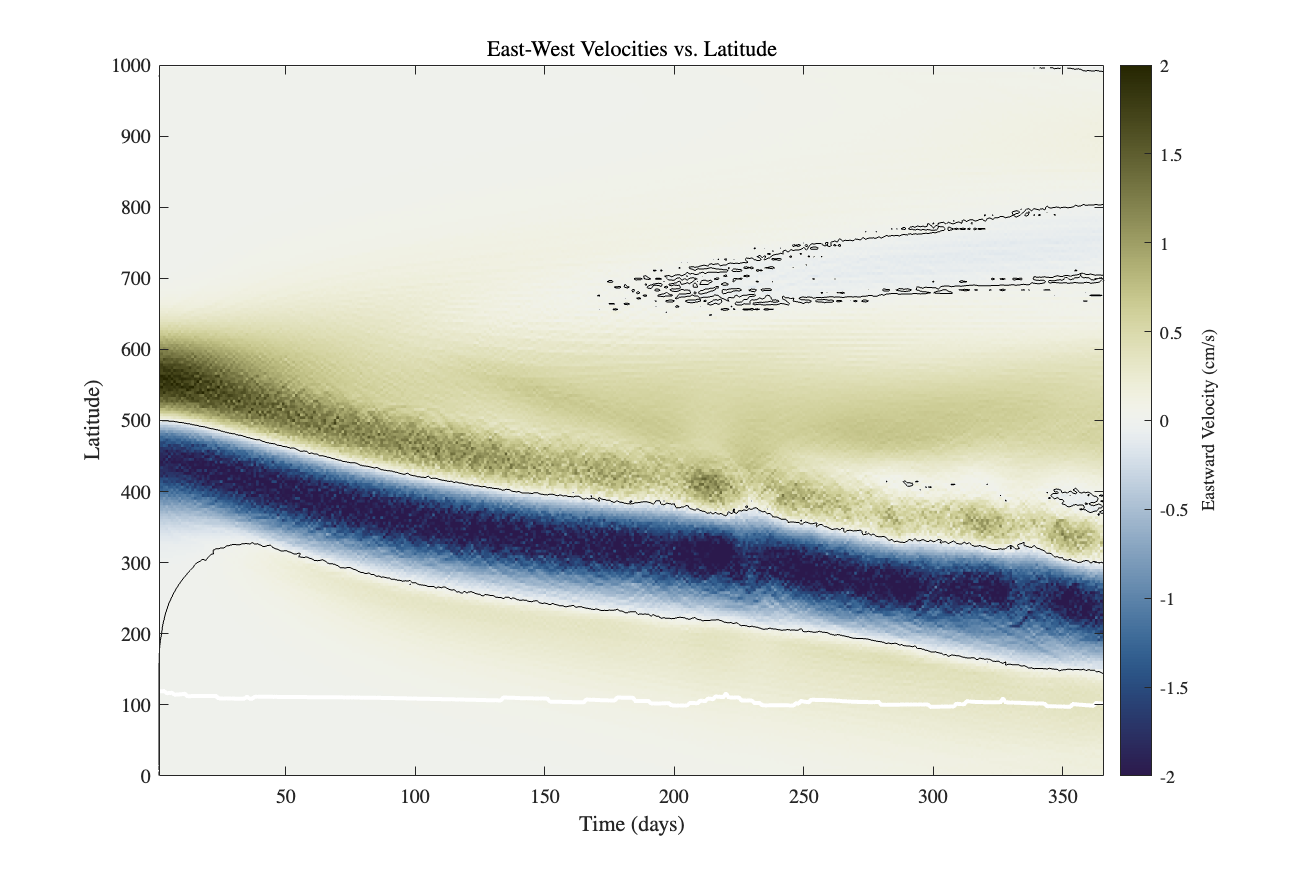

xbins=[0.5:1:size(drifter_x,1)+0.5];
dy=y(2)-y(1);
ybins=min(y)-dy/2:dy:max(y)+dy/2;
[mz,xmid,ymid,numz,stdz]=twodstats(drifter_t,drifter_y,drifter_u,xbins,ybins);

hf = figure();
hf.Position(3:4) = [1200,800];
colormap(crameri('broc'))

jpcolor(xmid,ymid,100*mz)
colormap(crameri('broc'))
clim([-.02 .02]*100),
hold on,contour(xmid,ymid,mz,[0 0],'k')
title('East-West Velocities vs. Latitude')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
axis([1 366 0 1000])
plot(1:length(R),R,'w','linewidth',2)

xlabel("Time (days)")
ylabel("Latitude)")

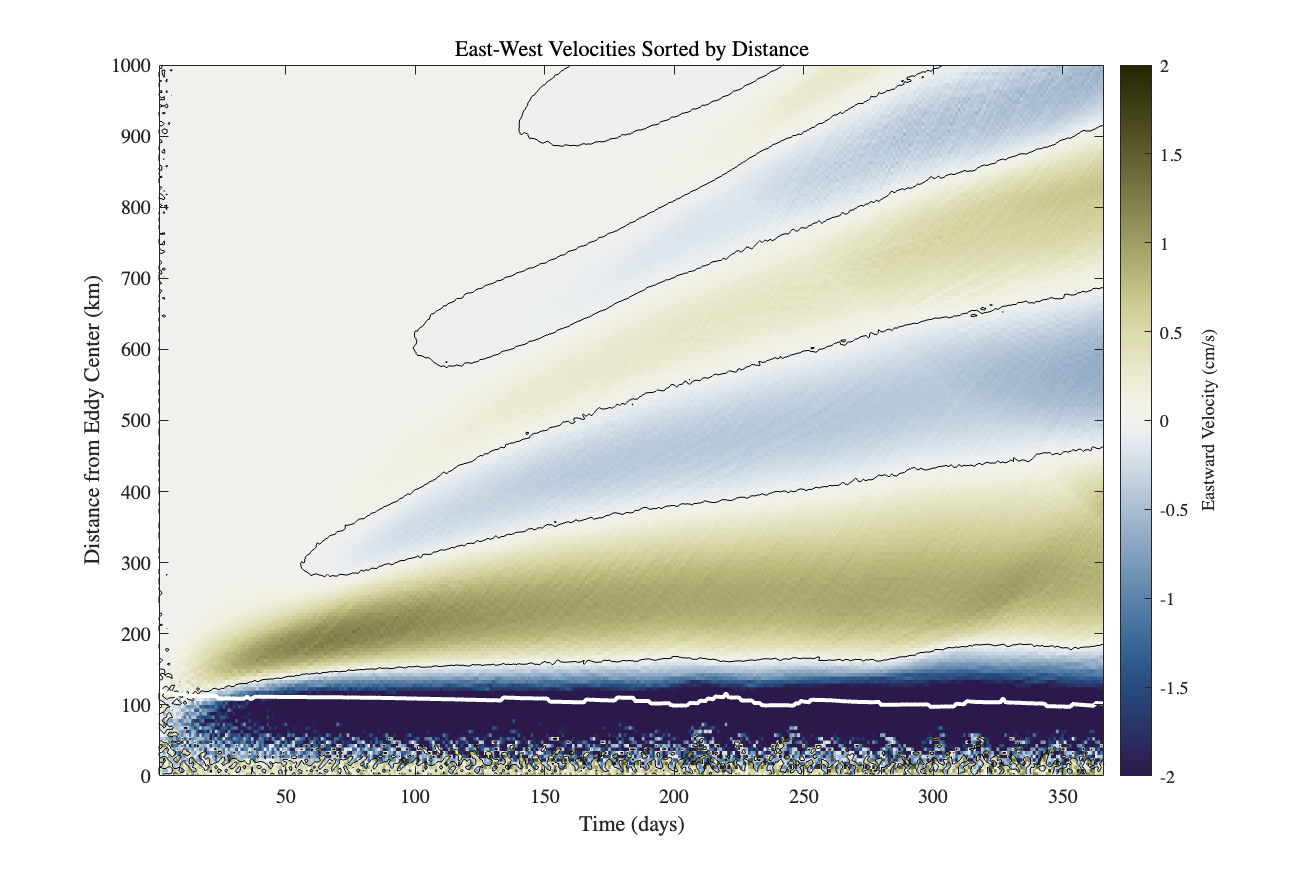

%finally we will look at the east-west transport sorted by distance
xbins=[0.5:1:size(drifter_x,1)+0.5];

drifter_d=zeros(size(drifter_t));
for k=1:size(drifter_d,1)
    %note!  should used periodized distance, which matters for very large distances
    drifter_d(k,:)=sqrt((drifter_x(k,:)-xo(k)).^2+(drifter_y(k,:)-yo(k)).^2);
end

dbins=[0:5:max(drifter_d,[],"all")];
[mz,xmid,ymid,numz,stdz]=twodstats(drifter_t,drifter_d,drifter_u,xbins,dbins);

hf = figure();
hf.Position(3:4) = [1200,800];
colormap(crameri('broc'))

jpcolor(xmid,ymid,100*mz)
colormap(crameri('broc'))
clim([-.02 .02]*100),
hold on,contour(xmid,ymid,mz,[0 0],'k')
title('East-West Velocities Sorted by Distance')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
axis([1 366 0 1000])
plot(1:length(R),R,'w','linewidth',2)

xlabel("Time (days)")
ylabel("Distance from Eddy Center (km)")

%Outtakes--- do not read

%first of all, what is the net transport? 
%can express as km^3/day, ok

dx = x(2)-x(1);%dx in km 
dA = dx.^2     %differential area in km^2, since dx=dy

dA = 15.2588

K = size(u,3); %number of time steps

%total area of fluid
max(x)*max(y)/1e6 %1.99 Mm^2

ans = 1.9883


%or if I attribute dA to each grid point
512*256*dA/1e6 %2 Mm^2

ans = 2

(max(x)+dx)*(max(y)+dx)/1e6 %2 Mm^2

ans = 2


%initial and final areas of the eddy
[~,~,~,R]=curvemoments(xc,yc);
Eo = pi*R(1)^2;   %44564 km^2
Ef = pi*R(end)^2; %32505 km^2
%------------------------------------------------------------------------------------
%east-west transport computations

%area of eastward and westward moving fluid
bool = (u>0); 
Ae = sum(bool(:),1)/K*dA/1e6 % 1.08 Mm^2 moving east

Ae = 1.0767

Aw = sum(~bool(:),1)/K*dA/1e6 % 0.92 Mm^2 moving west

Aw = 0.9233


%what is the transport? 
sum(u(bool),1)/K*dA*(1/1000*24*3600*365)/(2e6) %105.1 km/year

ans = 105.0908

sum(u(~bool),1)/K*dA*(1/1000*24*3600*365)/(2e6) %-105.1 km/year

ans = -105.0908

%a volume of fluid equal to the entire domain size moves 105 km east or west in a year 

%transport expressed in terms of intial eddy area 
sum(u(bool),1)/K*dA*(1/1000*24*3600*365)/Eo  %4716 km/year

ans = 4.7163e+03

sum(u(~bool),1)/K*dA*(1/1000*24*3600*365)/Eo %-4716 km/year

ans = -4.7163e+03


%Let's compare this with distance the eddy moves
xo(end)-xo(1) %-1164 km/year

ans = -1.1642e+03


%So the total transport due to the eddy is about 4x what you would expect
%based only on the transport from what is inside the core 

sum(u(bool),1)/K*dA*(1/1000*24*3600*365)/Eo/(xo(end)-xo(1))

ans = -4.0513


%how far do the areas of eastward and westward moving fluid move?  
sum(u(bool),1)/K*dA*(1/1000*24*3600*365)/(Ae*1e6)  %195.2 km/year

ans = 195.2031

sum(u(~bool),1)/K*dA*(1/1000*24*3600*365)/(Aw*1e6) %-227.6 km/year

ans = -227.6499

%------------------------------------------------------------------------------------
%north-south transport computations

%area of northward and southward moving fluid
bool = (v>0); 
An = sum(bool(:),1)/K*dA/1e6 % 1.27 Mm^2 moving east

An = 1.2689

As = sum(~bool(:),1)/K*dA/1e6 % 0.73 Mm^2 moving west

As = 0.7311


%what is the transport? 
sum(v(bool),1)/K*dA*(1/1000*24*3600*365)/(2e6) %133.8 km/year

ans = 133.7575

sum(v(~bool),1)/K*dA*(1/1000*24*3600*365)/(2e6) %-133.8 km/year

ans = -133.7575

%a volume of fluid equal to the entire domain size moves 133 km north or south in a year 

%transport expressed in terms of intial eddy area 
sum(v(bool),1)/K*dA*(1/1000*24*3600*365)/Eo  %6003 km/year

ans = 6.0029e+03

sum(v(~bool),1)/K*dA*(1/1000*24*3600*365)/Eo %-6003 km/year

ans = -6.0029e+03


%Let's compare this with distance the eddy moves
yo(end)-yo(1) %-210 km/year

ans = -210.0402


%So the total transport due to the eddy is about 30x what you would expect
%based only on the transport from what is inside the core 

sum(v(bool),1)/K*dA*(1/1000*24*3600*365)/Eo/(yo(end)-yo(1)) %28.6

ans = -28.5796


%how far do the areas of eastward and westward moving fluid move?  
sum(v(bool),1)/K*dA*(1/1000*24*3600*365)/(An*1e6)  %210.8 km/year

ans = 210.8320

sum(v(~bool),1)/K*dA*(1/1000*24*3600*365)/(As*1e6) %-365.9 km/year

ans = -365.8844

%------------------------------------------------------------------------------------
%takeaway: there is a very efficient north-south displacement, 10x more
%efficient than east-west displacement by comparison to the eddy movement
%------------------------------------------------------------------------------------

% ax=nexttile;
% contourf(xmid,ymid,stdu,100),nocontours, hold on,axis equal
% colormap(ax,flipud(crameri('davos')))
% clim([0 .04]),axis([-1 1 -1 1]*250)
% cellplot(xpc(1:14:end),ypc(1:14:end),'0.25D')
% 
% ax=nexttile;
% contourf(xmid,ymid,stdv,100),nocontours, hold on,axis equal
% colormap(ax,flipud(crameri('davos')))
% clim([0 .04]),axis([-1 1 -1 1]*250)
% cellplot(xpc(1:14:end),ypc(1:14:end),'0.25D')
